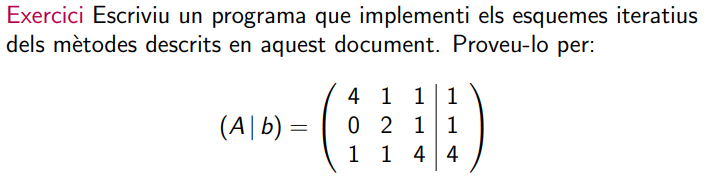

A = E + D + F

J -> B=-D^-1*(E+F) | c D^-1*b

A =  [4 1 1; 0 2 1; 1 1 4];
b = [1 1 4]';

% JACOBI
D= diag(diag(A));       % Diagonal
d= diag(1./diag(A));    % Inversa diagonal
L= tril(A,-1);          % Triangular inferior
U= triu(A,1);           % Triangular superior

Bj= -d*(L + U);
cj= d*b;

% GAUSS
C = inv(L + D);
Bgs = -C * U;
cgs = C * b;

n= 10;
xJ = zeros(size(b));
xG = zeros(size(b));
residus = zeros(n,2);

for i=1:n
    xJ = Bj*xJ + cj;     % Jacobi
    xG = Bgs*xG + cgs;   % Gauss
    residus(i,1) = norm(b-A*xJ,1);
    residus(i,2) = norm(b-A*xG,1);
end

format short g
table(residus)

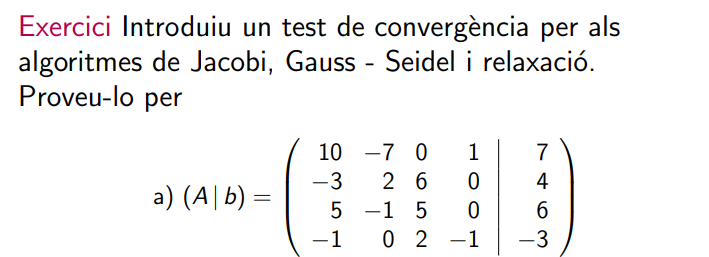

clear;

A= [10 -7 0 1; -3 2 6 0; 5 -1 5 0; -1 0 2 -1];
b= [7 4 6 -3]';



D= diag(diag(A));       % Diagonal
d= diag(1./diag(A));    % Inversa diagonal
L= tril(A,-1);          % Triangular inferior
U= triu(A,1);           % Triangular superior

w= 0.95;

% JACOBI relaxacio
C = d;
Bsor= C*((1-w)*D - w*(L+U));
Csor= w*C*b;

% GAUSS relaxacio

